# **MAKIMA Fittings with growth curves**

**Loyal Murphy - September 13, 2023**

Now, I am getting the individual growth curves with the individual data

### **Initialization**

clear variables
clc
clf

# **DATA EXTRACTION**

### Extract Methanotroph Data

scans = dir('*.mat');

all_meth_OD = {};
ms = 0; %Initialize counter

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if startsWith(n,'M')
        ms = ms + 1;
        meth_data = load(n);
        if length(fieldnames(meth_data)) == 3
            j = fieldnames(meth_data);
            data = meth_data.(j{1});
            factor = meth_data.(j{2});
            to = meth_data.(j{3});
            
            %Get the OD values (multiplying by the factor)
            for x = 1:size(data,1)
                odValues(x) = data{x,1}.Abs(data{x,1}.nm == 600);
            end
            all_meth_OD{ms,1} = reshape(odValues,[size(data,1)/3,3]).*factor';
            if ms == 3
                all_meth_OD{ms,1}(13,2) = 5.46;
            end
            %Get the times
            pts = size(data,1)/3;
            time_matrix = zeros(pts,1); %Initialize time_matrix
            for k = 1:pts
                time_matrix(k) = hours(mean([data{k,2},...
                    data{k+pts,2},...
                    data{k+2*pts,2}]) - to);
            end
            all_meth_OD{ms,2} = time_matrix;

        elseif length(fieldnames(meth_data)) == 2
            j = fieldnames(meth_data);
            
            %Get the OD values (factor already multiplied)
            all_meth_OD{ms,1} = meth_data.(j{1});
            
            %Get the time values (initial time already subtracted)
            all_meth_OD{ms,2} = meth_data.(j{2});
        end

    clear data factor to odValues j k x meth_data pts
    end
end
clear n ms time_matrix i

### Extract Microalgae Data

scans = dir('*.mat');

all_photo_gDCW = {};
ms = 0; %Initialize counter

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if startsWith(n,'P')
        ms = ms + 1;
        photo_data = load(n);
        if length(fieldnames(photo_data)) == 3
            j = fieldnames(photo_data);
            data = photo_data.(j{1});
            factor = photo_data.(j{2});
            to = photo_data.(j{3}); 
            
            %Get the OD values (multiplying by the factor)
            for x = 1:size(data,1)
                gDCWValues(x) = data{x,1}.Abs(data{x,1}.nm == 750);
            end
            all_photo_gDCW{ms,1} = reshape(gDCWValues,[size(data,1)/3,3]).*factor';
                            
            %Get the times
            pts = size(data,1)/3;
            time_matrix = zeros(pts,1); %Initialize time_matrix
            for k = 1:pts
                time_matrix(k) = hours(mean([data{k,2},...
                    data{k+pts,2},...
                    data{k+2*pts,2}]) - to);
            end
            all_photo_gDCW{ms,2} = time_matrix;

        elseif length(fieldnames(photo_data)) == 2
            j = fieldnames(photo_data);
            
            %Get the OD values (factor already multiplied)
            all_photo_gDCW{ms,1} = photo_data.(j{1});
            
            %Get the time values (initial time already subtracted)
            all_photo_gDCW{ms,2} = photo_data.(j{2});
        end

    clear data factor to gDCWValues j k x photo_data pts
    end
end
clear n ms time_matrix i 

### Extract Coculture OD Data

scans = dir('*.mat');

all_coc_OD = {};
ms = 0; %Initialize counter

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if contains(n,'OD') && (startsWith(n,'C') || startsWith(n,'F') || startsWith(n,'L'))
        ms = ms + 1;
        cOD_data = load(n);
        if length(fieldnames(cOD_data)) == 3
            j = fieldnames(cOD_data);
            data = cOD_data.(j{1});
            factor = cOD_data.(j{2});
            to = cOD_data.(j{3});
            
            %Get the OD values (multiplying by the factor)
            for x = 1:size(data,1)
                odValues(x) = data{x,1}.Abs(data{x,1}.nm == 750);
            end
            all_coc_OD{ms,1} = reshape(odValues,[size(data,1)/3,3]).*factor';
                            
            %Get the times
            pts = size(data,1)/3;
            time_matrix = zeros(pts,1); %Initialize time_matrix
            for k = 1:pts
                time_matrix(k) = hours(mean([data{k,2},...
                    data{k+pts,2},...
                    data{k+2*pts,2}]) - to);
            end
            all_coc_OD{ms,2} = time_matrix;

        elseif length(fieldnames(cOD_data)) == 2
            j = fieldnames(cOD_data);
            
            %Get the OD values (factor already multiplied)
            all_coc_OD{ms,1} = cOD_data.(j{1});
            
            %Get the time values (initial time already subtracted)
            all_coc_OD{ms,2} = cOD_data.(j{2});
        end

    clear data factor to odValues j k x cOD_data pts
    end
end
clear n ms time_matrix i

### Extract Coculture gDCW data

scans = dir('*.mat');

all_coc_gDCW = {};
ms = 0; %Initialize counter

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if contains(n,'gDCW') && (startsWith(n,'C') || startsWith(n,'F') || startsWith(n,'L'))
        ms = ms + 1;
        cDW_data = load(n);
        if length(fieldnames(cDW_data)) == 3
            j = fieldnames(cDW_data);
            data = cDW_data.(j{1});
            factor = cDW_data.(j{2});
            to = cDW_data.(j{3});
            
            %Get the OD values (multiplying by the factor)
            for x = 1:size(data,1)
                gDCWValues(x) = data{x,1}.Abs(data{x,1}.nm == 750);
            end
            all_coc_gDCW{ms,1} = reshape(gDCWValues,[size(data,1)/3,3]).*factor';
                            
            %Get the times
            pts = size(data,1)/3;
            time_matrix = zeros(pts,1); %Initialize time_matrix
            for k = 1:pts
                time_matrix(k) = hours(mean([data{k,2},...
                    data{k+pts,2},...
                    data{k+2*pts,2}]) - to);
            end
            all_coc_gDCW{ms,2} = time_matrix;

        elseif length(fieldnames(cDW_data)) == 2
            j = fieldnames(cDW_data);
            
            %Get the OD values (factor already multiplied)
            all_coc_gDCW{ms,1} = cDW_data.(j{1});
            
            %Get the time values (initial time already subtracted)
            all_coc_gDCW{ms,2} = cDW_data.(j{2});
        end

    clear data factor to gDCWValues j k x cDW_data pts
    end
end
clear n ms time_matrix i 

%Remove scan data to keep workspace clean
clear scans

# **PLOT GROWTH CURVES and GROWTH RATES**

### Methanotrophs

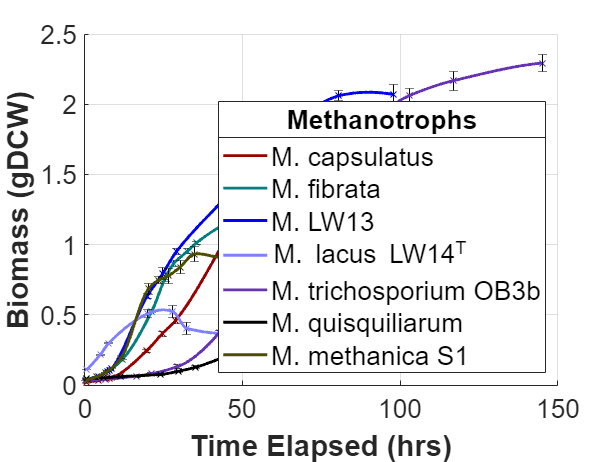

Meth_titles = ["Cap";"Fib";"LW13";"LW14T";"OB3b";"QQ";"S1"];
gDCW_conversion = [0.235,0.369,0.382,0.659,0.460,0.4,0.447];
Colors = {[0.6 0 0],[0 0.5 0.5],[0 0 1],[0.5 0.5 1],[0.4 0.2 0.7],[0 0 0],[0.3 0.3 0]};
n = 100000;
makx = zeros(n,length(Meth_titles));
maky = zeros(n,length(Meth_titles));

for i = 1:size(all_meth_OD,1)
    ODs = all_meth_OD{i,1};
    gDCWs = ODs*gDCW_conversion(i);
    Times = all_meth_OD{i,2};
    meangDCWs = mean(gDCWs,2);
    stdgDCWs = std(gDCWs,1,2);
    makx = linspace(min(Times),max(Times),n);
    maky = makima(Times,meangDCWs,makx);

    % Growth Rate Values
    mus = zeros([size(gDCWs,1)-1,size(gDCWs,2)]);
    for j = 1:size(gDCWs,1)-1
        mus(j,:) = (log(gDCWs(j+1,:))-log(gDCWs(j,:)))/(Times(j+1)-Times(j));
        mu_times(j) = (Times(j+1)+Times(j))/2;
    end

    makx_mu = makx(2:end);
    maky_mu = log(maky(2:end)./maky(1:end-1))./(makx(2:end) - makx(1:end-1));
    % Growth Rate Values

    figure(1)
    hold on 
    plot(Times,meangDCWs,'x','LineStyle','none','Color',Colors{i});
    errorbar(Times,meangDCWs,stdgDCWs,'LineStyle','none','Color','k');
    plot(makx,maky,'-','LineWidth',2,'Color',Colors{i});
    ax = gca;
    ax.FontSize = 18;
    xlabel('Time Elapsed (hrs)','FontSize',20,'FontWeight','bold');
    ylabel('Biomass (gDCW)','FontSize',20,'FontWeight','bold');
    lgd = legend('','','M. capsulatus','','','M. fibrata','','','M. LW13','','','M. lacus LW14^{T}','','','M. trichosporium OB3b','','','M. quisquiliarum','','','M. methanica S1','location','southeast','fontsize',18);
    title(lgd,'Methanotrophs')
    grid on
    axis([0 150 0 2.5]);
    hold off

    % figure(20)
    % subplot(2,4,i)
    % hold on
    % plot(mu_times,mean(mus,2),'s','Color',Colors{i},'LineStyle','none');
    % errorbar(mu_times,mean(mus,2),std(mus,1,2),'LineStyle','none','Color','k');
    % plot(makx_mu,maky_mu,'-','LineWidth',2,'Color',Colors{i});
    % ax.FontSize = 18;
    % grid on
    % axis([0 100 0 0.2]);
    % title(Meth_titles(i))
    % ylabel('Growth Rate (1/hr)')
    % xlabel('Time Elapsed (hr)')
    % hold off

    clear ODs Times mus mu_times makx maky makx_mu maky_mu
end

### Microalgae

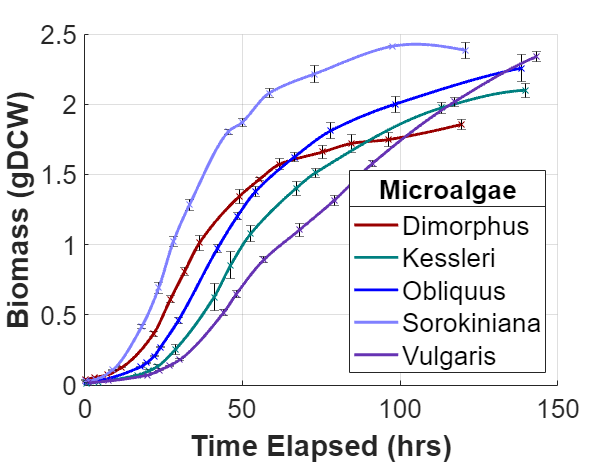

Photo_titles = ["Dimorphus";"Kessleri";"Obliquus";"Sorokiniana";"Vulgaris"];
Colors = {[0.6 0 0],[0 0.5 0.5],[0 0 1],[0.5 0.5 1],[0.4 0.2 0.7]};
gDCW_conversion = [0.52,1,1,0.39,1]; %Dimorphus and Sorokiniana data are OD's!

for i = 1:size(all_photo_gDCW,1)
    raws = all_photo_gDCW{i,1};
    gDCWs = raws*gDCW_conversion(i);
    Times = all_photo_gDCW{i,2};
    meangDCWs = mean(gDCWs,2);
    stdgDCWs = std(gDCWs,1,2);
    makx = linspace(min(Times),max(Times),n);
    maky = makima(Times,meangDCWs,makx);

    mus = zeros([size(gDCWs,1)-1,size(gDCWs,2)]);
    for j = 1:size(gDCWs,1)-1
        mus(j,:) = (log(gDCWs(j+1,:))-log(gDCWs(j,:)))/(Times(j+1)-Times(j));
        mu_times(j) = (Times(j+1)+Times(j))/2;
    end
    makx_mu = makx(2:end);
    maky_mu = log(maky(2:end)./maky(1:end-1))./(makx(2:end) - makx(1:end-1));

    figure(40)
    hold on 
    plot(Times,meangDCWs,'x','LineStyle','none','Color',Colors{i});
    errorbar(Times,meangDCWs,stdgDCWs,'LineStyle','none','Color','k');
    plot(makx,maky,'-','LineWidth',2,'Color',Colors{i});
    ax = gca;
    ax.FontSize = 18;
    xlabel('Time Elapsed (hrs)','FontSize',20,'FontWeight','bold');
    ylabel('Biomass (gDCW)','FontSize',20,'FontWeight','bold');
    lgd2 = legend('','','Dimorphus','','','Kessleri','','','Obliquus','','','Sorokiniana','','','Vulgaris','location','southeast','fontsize',18);
    title(lgd2,'Microalgae')
    grid on
    axis([0 150 0 2.5]);
    hold off

    % figure(40)
    % subplot(2,3,i)
    % hold on
    % plot(mu_times,mean(mus,2),'s','Color',Colors{i},'LineStyle','none');
    % errorbar(mu_times,mean(mus,2),std(mus,1,2),'LineStyle','none','Color','k');
    % plot(makx_mu,maky_mu,'-','LineWidth',2,'Color',Colors{i});
    % ax.FontSize = 18;
    % grid on
    % axis([0 100 0 0.2]);
    % title(Photo_titles(i))
    % ylabel('Growth Rate (1/hr)')
    % xlabel('Time Elapsed (hr)')
    % hold off

    clear ODs Times mus mu_times makx maky makx_mu maky_mu
end

### Cocultures (OD's)

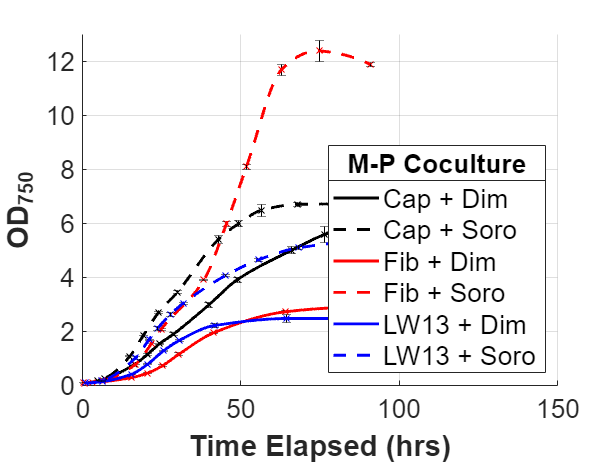

Coc_titles = ["Cap + Dim";"Cap + Soro";"Fib + Dim";"Fib + Soro";"LW13 + Dim";"LW13 + Soro"];
Colors = {'k','k','r','r','b','b'};
Styles = {'-','--','-','--','-','--'};

for i = 1:size(all_coc_OD,1)
    ODs = all_coc_OD{i,1};
    Times = all_coc_OD{i,2};
    meangODs = mean(ODs,2);
    stdgODs = std(ODs,1,2);
    makx = linspace(min(Times),max(Times),n);
    maky = makima(Times,meangODs,makx);

    mus = zeros([size(ODs,1)-1,size(ODs,2)]);
    for j = 1:size(ODs,1)-1
        mus(j,:) = (log(ODs(j+1,:))-log(ODs(j,:)))/(Times(j+1)-Times(j));
        mu_times(j) = (Times(j+1)+Times(j))/2;
    end
    makx_mu = makx(2:end);
    maky_mu = log(maky(2:end)./maky(1:end-1))./(makx(2:end) - makx(1:end-1));

    figure(60)
    hold on 
    plot(Times,meangODs,'x','LineStyle','none','Color',Colors{i});
    errorbar(Times,meangODs,stdgODs,'LineStyle','none','Color','k');
    plot(makx,maky,'LineStyle',Styles{i},'LineWidth',2,'Color',Colors{i});
    ax = gca;
    ax.FontSize = 18;
    xlabel('Time Elapsed (hrs)','FontSize',20,'FontWeight','bold');
    ylabel('OD_{750}','FontSize',20,'FontWeight','bold');
    lgd3 = legend('','','Cap + Dim','','','Cap + Soro','','','Fib + Dim','','','Fib + Soro','','','LW13 + Dim','','','LW13 + Soro','location','southeast','fontsize',18);
    title(lgd3,'M-P Coculture')
    grid on
    axis([0 150 0 13]);
    hold off

    % figure(60)
    % subplot(2,3,i)
    % hold on
    % plot(mu_times,mean(mus,2),'s','Color',Colors{i},'LineStyle','none');
    % errorbar(mu_times,mean(mus,2),std(mus,1,2),'LineStyle','none','Color','k');
    % plot(makx_mu,maky_mu,'LineStyle',Styles{i},'LineWidth',2,'Color',Colors{i});
    % ax.FontSize = 18;
    % grid on
    % axis([0 100 0 0.2]);
    % title(Coc_titles(i))
    % ylabel('Growth Rate (1/hr)')
    % xlabel('Time Elapsed (hr)')
    % hold off

    clear ODs Times mus mu_times makx maky makx_mu maky_mu
end

### Cocultures (gDCW's)

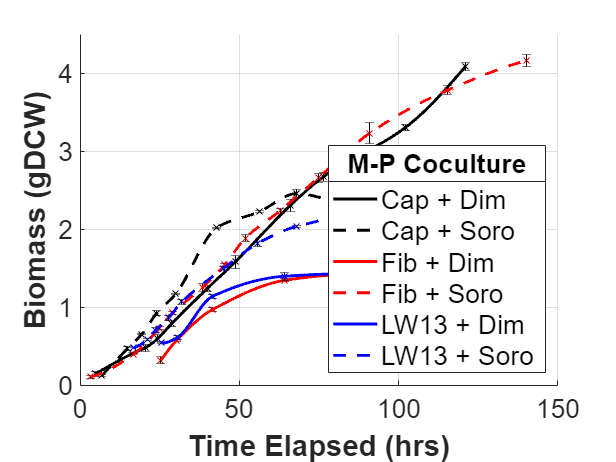

Coc_titles = ["Cap + Dim";"Cap + Soro";"Fib + Dim";"Fib + Soro";"LW13 + Dim";"LW13 + Soro"];
Colors = {'k','k','r','r','b','b'};
Styles = {'-','--','-','--','-','--'};

for i = 1:size(all_coc_gDCW,1)
    gDCWs = all_coc_gDCW{i,2}*1000 - 0.345; %NOTE: These are backwards from Coculture OD's
    Times = all_coc_gDCW{i,1}; %NOTE: These are backwards from Coculture OD's
    meangDCWs = mean(gDCWs,1); %NOTE: Different dimension from Coculture OD's
    stdgDCWs = std(gDCWs,1,1);
    makx = linspace(min(Times),max(Times),n);
    maky = makima(Times,meangDCWs,makx);

    mus = zeros([size(gDCWs,1),size(gDCWs,2)-1]);
    for j = 1:size(gDCWs,2)-1
        mus(:,j) = (log(gDCWs(:,j+1))-log(gDCWs(:,j)))/(Times(j+1)-Times(j));
        mu_times(j) = (Times(j+1)+Times(j))/2;
    end
    makx_mu = makx(2:end);
    maky_mu = log(maky(2:end)./maky(1:end-1))./(makx(2:end) - makx(1:end-1));

    figure(80)
    hold on 
    plot(Times,meangDCWs,'x','LineStyle','none','Color',Colors{i});
    errorbar(Times,meangDCWs,stdgDCWs,'LineStyle','none','Color','k');
    plot(makx,maky,'LineStyle',Styles{i},'LineWidth',2,'Color',Colors{i});
    ax = gca;
    ax.FontSize = 18;
    xlabel('Time Elapsed (hrs)','FontSize',20,'FontWeight','bold');
    ylabel('Biomass (gDCW)','FontSize',20,'FontWeight','bold');
    lgd4 = legend('','','Cap + Dim','','','Cap + Soro','','','Fib + Dim','','','Fib + Soro','','','LW13 + Dim','','','LW13 + Soro','location','southeast','fontsize',18);
    title(lgd4,'M-P Coculture')
    grid on
    axis([0 150 0 4.5]);
    hold off

    % figure(80)
    % subplot(2,3,i)
    % hold on
    % plot(mu_times,mean(mus,1),'s','Color',Colors{i},'LineStyle','none');
    % errorbar(mu_times,mean(mus,1),std(mus,1,1),'LineStyle','none','Color','k');
    % plot(makx_mu,maky_mu,'LineStyle',Styles{i},'LineWidth',2,'Color',Colors{i});
    % ax.FontSize = 18;
    % grid on
    % axis([0 100 0 0.2]);
    % title(Coc_titles(i))
    % ylabel('Growth Rate (1/hr)')
    % xlabel('Time Elapsed (hr)')
    % hold off

    clear ODs Times mus mu_times makx maky makx_mu maky_mu
end